# EECS 965 Homework 01                                 William Powers 2025

#### ***1. Using the MAP decision criterion, determine a simplified sufficient statistic ***$T_s(x, H_i)$*** for each hypothesis.***

Before finding a sufficient statistic and forming the MAP decision criterion, the likelihood functions for each hypotheses $H_a$, $H_B$, and $H_c$ must be expressed. Given that sources $s_a$, $s_b$, and $s_c$ are all deterministic two dimensional vectors contaminated with Normally distrubted white noise, the liklihood functions of each hypothesis producing the measurement will also be two dimensional Normally distributed.


$$p(\mathbf{x} | H_a) =
 \frac{1}{\sqrt{(2\pi)^k\text{det}(\mathbf{\Sigma})}} 
\text{exp} \left( -\frac{1}{2} (\mathbf{x}-\mathbf{\mu_a})^H \mathbf{\Sigma}^{-1} (\mathbf{x}-\mathbf{\mu_a}) \right)$$
 


$$p(\mathbf{x} | H_b) =
 \frac{1}{\sqrt{(2\pi)^k\text{det}(\mathbf{\Sigma})}} 
\text{exp} \left( -\frac{1}{2} (\mathbf{x}-\mathbf{\mu_b})^H \mathbf{\Sigma}^{-1} (\mathbf{x}-\mathbf{\mu_b}) \right)$$



$$p(\mathbf{x} | H_c) =
 \frac{1}{\sqrt{(2\pi)^k\text{det}(\mathbf{\Sigma})}} 
\text{exp} \left( -\frac{1}{2} (\mathbf{x}-\mathbf{\mu_c})^H \mathbf{\Sigma}^{-1} (\mathbf{x}-\mathbf{\mu_c}) \right)$$



$$\mathbf{\Sigma}=
\left[
\begin{array}{cc}
\sigma_w^2 & 0 \\
0 & \sigma_w^2
\end{array}
\right]$$
    
$$\mathbf{\mu_a}=[0, 0]^T$$
    
$$\mathbf{\mu_b}=[\sqrt{2}, \sqrt{2}]^T$$
    
$$\mathbf{\mu_c}=[2\sqrt{2}, 2\sqrt{2}]^T$$


These liklihood functions are plotted below for a arbitrary standard deviation.

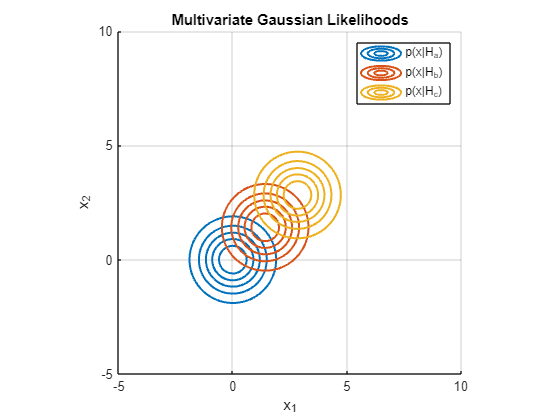

% parameters
sigma_w = 1;
Sigma = sigma_w^2 * eye(2);

% define mean vectors for each hypothesis
mu = [0, 0; sqrt(2), sqrt(2); 2*sqrt(2), 2*sqrt(2)];

% x1, x2 support grid
x1 = linspace(-5, 10, 200);
x2 = linspace(-5, 10, 200);
[X1, X2] = meshgrid(x1, x2);
X = [X1(:), X2(:)];

% plot each PDF
figure('Name', 'Multivariate Liklihood Functions'); hold on; grid on;
colors = lines(size(mu,1));

for i = 1:size(mu,1)
    % multivariate Gaussian pdf values
    pdf_vals = mvnpdf(X, mu(i,:), Sigma);
    pdf_vals = reshape(pdf_vals, length(x2), length(x1));
    
    % contour plot
    contour(X1, X2, pdf_vals, 5, 'LineWidth', 1.5, 'Color', colors(i,:));
end

xlabel('x_1'); ylabel('x_2');
title('Multivariate Gaussian Likelihoods');
legend('p(x|H_a)', 'p(x|H_b)', 'p(x|H_c)');
axis equal;

The problem states that each of the three hypotheses are equally probable, using this a priori assumption, the a posteriori probabilities are calcualted as


$$Pr(H_a|\mathbf{x}) = 
\frac{ p(\mathbf{x} | H_a) (1/3)} { \sum_{i=1, 2, 3}p(\mathbf{x}|H_i) (1/3) } = 
\frac{ p(\mathbf{x} | H_a) } { p(\mathbf{x}|H_a) + p(\mathbf{x}|H_b) + p(\mathbf{x}|H_c) }$$



$$Pr(H_b|\mathbf{x}) = 
\frac{ p(\mathbf{x} | H_b) (1/3)} { \sum_{i=1, 2, 3}p(\mathbf{x}|H_i) (1/3) } = 
\frac{ p(\mathbf{x} | H_b) } { p(\mathbf{x}|H_a) + p(\mathbf{x}|H_b) + p(\mathbf{x}|H_c) }$$



$$Pr(H_c|\mathbf{x}) = 
\frac{ p(\mathbf{x} | H_c) (1/3)} { \sum_{i=1, 2, 3}p(\mathbf{x}|H_i) (1/3) } = 
\frac{ p(\mathbf{x} | H_c) } { p(\mathbf{x}|H_a) + p(\mathbf{x}|H_b) + p(\mathbf{x}|H_c) }$$


To form a sufficient statistic, we observe that it is unnecessary to compute the full posterior probability for each hypothesis; instead we just need to determine which posterior is greatest. Because the denominators in the expressions are identical, they are multiplied to the right hand side and grouped into sufficient statistic $T_s(\mathbf{x}, H_i)$.


$$T_s(\mathbf{x}, H_i) =  \left( p(\mathbf{x}|H_a) + p(\mathbf{x}|H_b) + p(\mathbf{x}|H_c) \right) Pr(H_i| \mathbf{x}) = p(\mathbf{x} | H_i)$$


Further algebraic simplifications are as follows


$$T_s(\mathbf{x}, H_i) = 
\frac{1}{2\pi\sigma_w^4}
\text{exp} \left(
-\frac{1}{2} 

\left[
\begin{array}{cc}
x_1 - \mu_1 \\
x_2 - \mu_2
\end{array}
\right]^H

\left[
\begin{array}{cc}
1/\sigma_w^2 & 0 \\
0 & 1/\sigma_w^2
\end{array}
\right]

\left[
\begin{array}{cc}
x_1 - \mu_1 \\
x_2 - \mu_2
\end{array}
\right]
\right)$$



$$T_s(\mathbf{x}, H_i) = 
\frac{1}{2\pi\sigma_w^2}
\text{exp} \left(
-\frac{(x_1 - \mu_1)^2 + (x_2 - \mu_2)^2}
{2\sigma_w^2}

\right)$$



$$T_s(\mathbf{x}, H_i) = 

(x_1 - \mu_{i1})^2 + (x_2 - \mu_{i2})^2
$$


Rewriting this generalized form for each hypothesis gives three scalar sufficient statistics!


$$T_s(\mathbf{x}, H_a) = 

(x_1)^2 + (x_2)^2
$$
    
$$T_s(\mathbf{x}, H_b) = 

(x_1 - \sqrt{2})^2 + (x_2 - \sqrt{2})^2
$$
    
$$T_s(\mathbf{x}, H_c) = 

(x_1 - 2\sqrt{2})^2 + (x_2 - 2\sqrt{2})^2
$$


#### *2. Using these sufficient statistics, express a specific MAP decision rule for each of the three hypotheses.*

The three sufficient statistics defined in part 1 can now be used to determine the maximum a posteriori decision rule. The three rules are,


$$\text{Choose} \ H_a \ \text{if} \ T_s(\mathbf{x}, H_a) > T_s(\mathbf{x}, H_b) \ \ \text{and} \ \ T_s(\mathbf{x}, H_a) > T_s(\mathbf{x}, H_c)$$



$$\text{Choose} \ H_b \ \text{if} \ T_s(\mathbf{x}, H_b) > T_s(\mathbf{x}, H_a) \ \ \text{and} \ \ T_s(\mathbf{x}, H_b) > T_s(\mathbf{x}, H_c)$$



$$\text{Choose} \ H_c \ \text{if} \ T_s(\mathbf{x}, H_c) > T_s(\mathbf{x}, H_a) \ \ \text{and} \ \ T_s(\mathbf{x}, H_c) > T_s(\mathbf{x}, H_b)$$


#### *3. From these decision rules, extract a single scalar detection statistic *$T_d(\mathbf{x})$, and define specifically the decision region for each hypothesis in terms of this detection statistic.

For each of the decision rules above, a single scalar detection statistic $T_d(\mathbf{x})$ is expressed by moving all terms dependent on the measurement to the left hand side of the equation, and all terms dependent on the hypotheses to the left.

Choose   $H_a$    if    $x_1 + x_2 > \sqrt{2}$    and    $x_1 + x_2 > 2\sqrt{2}$

Choose   $H_b$    if   $x_1 + x_2 < \sqrt{2}$    and     $x_1 + x_2 > 3\sqrt{2}$

Choose   $H_c$   if   $x_1 + x_2 < 2\sqrt{2}$    and    $x_1 + x_2 < 3\sqrt{2}$

The redundant terms are removed and the stricter domains are kept producing the following decision regions using the decision statistic $T_d(\mathbf{x}) = x_1 + x_2$.

Choose $H_a$ if $T_d(\mathbf{x}) <\sqrt{2}$

Choose $H_b$ if $\sqrt{2} < T_d(\mathbf{x})  < 3\sqrt{2}$

Choose $H_c$ if $T_d(\mathbf{x})  > 3\sqrt{2}$

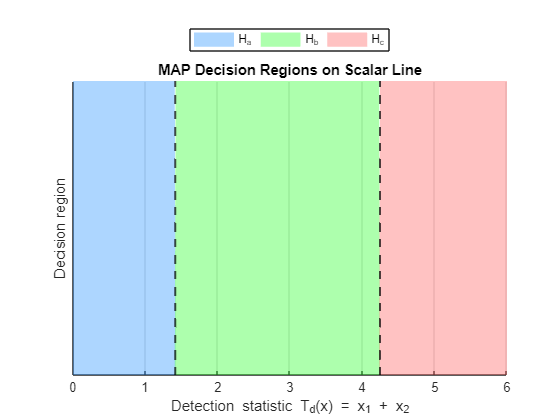

% thresholds
tau1 = sqrt(2);
tau2 = 3*sqrt(2);

% range for detection statistic
Td = linspace(0, 6, 500);

% decision regions: Ha (low), Hb (middle), Hc (high)
region = zeros(size(Td));
region(Td < tau1) = 1;
region(Td >= tau1 & Td <= tau2) = 2;
region(Td > tau2) = 3;

% plot decision regions
figure('Name', 'Decision Regions'); hold on;
area(Td, region==1, 'FaceColor',[0.2 0.6 1], 'EdgeColor','none', 'FaceAlpha',0.4);
area(Td, region==2, 'FaceColor',[0.2 1 0.2], 'EdgeColor','none', 'FaceAlpha',0.4);
area(Td, region==3, 'FaceColor',[1 0.4 0.4], 'EdgeColor','none', 'FaceAlpha',0.4);
xline(tau1,'k--','LineWidth',1.5);
xline(tau2,'k--','LineWidth',1.5);
xlabel('Detection statistic T_d(x) = x_1 + x_2');
ylabel('Decision region');
yticks([]);
legend({'H_a','H_b','H_c'}, 'Location','northoutside','Orientation','horizontal');
title('MAP Decision Regions on Scalar Line');
grid on;